# The WIM method for CICE6.

As CICE6 does not include wave propagation through ice, for wave forcing, we must attach a *waves-in-ice module* (WIM). This particular WIM has the following method:

- Take the signfiicant wave height, peak period and mean wave direction for the most northern ice-free cell.

- Apply a directional filter such that waves only propagate along longitudinal lines.

- Define the wave spectrum using a Bretschneider spectrum at this ice-free cell.

- Propagate through the ice (towards Antarctica) using the attenuation coefficent from Meylan et al. (2014).

- Calculate the signfiicant wave height and peak period for the propagated waves and feed this into CICE6.

% Preamble
clc
clear all
close all
addpath functions
%cd .. % Move up one directory
day = 9;
month = 1;
year = 2005;
sector = "SA";
if day < 9
    date = sprintf('%d-0%d-0%d', year, month, day);
else
    date = sprintf('%d-0%d-%d', year, month, day);
end
case_name = '31freq';
ticker = 1;
SIC = 0.15; 
filename = "/Volumes/NoahDay5TB/cases/31freq/history/iceh.2008-07-30.nc";%/Volumes/NoahDay5TB/cases/forcingnowaves/history/iceh.2005-07.nc";%"prra_input4MIPs_atmosphericState_OMIP_MRI-JRA55-do-1-5-0_gr_196201010130-196212312230.nc";
filename = "/Users/noahday/Maths1/access-forcing-2010-fixed-ic/history/2019/iceh.2019-09-01.nc";
filename = "/Volumes/NoahDay5TB/WIMonAlessandroRun/history/iceh.2017-09-01.nc";
%strcat('cases/',case_name,"/history/iceh.",date,".nc");
% '/Users/noahday/Gadi/2010/JRA55_03hr_forcing_2010.nc';%'grid/gridded_ww3.glob_24m.200501.nc'; 
%filename = 'DATA/CESM/MONTHLY/ocean_forcing_clim_2D_gx1.20210330.nc';
% Read the header
%ncdisp(filename)
sector = "SH";
grid = 'om2';
[lat,lon] = grid_read(grid);

%% Finding the ice edge
aice_data = data_format_sector(filename,"aice",sector);

[lat_ice_edge, lon_ice_edge,edge] = find_ice_edge(aice_data,SIC,sector,lat,lon);


% Plot areal ice concentration
 
conFigure(11,1)
f = figure;
[p,a] = map_plot(aice_data,"aice","SH",'om2');

plotm(lat_ice_edge,lon_ice_edge,'-','color',0.7*[0.4660 0.6740 0.1880],'LineWidth',2) % Dark green
t = textm(lat_ice_edge(20)-5,lon_ice_edge(300),sprintf('SIC = %g\n ice edge',SIC),'HorizontalAlignment','right');
t.Color = 0.7*[0.4660 0.6740 0.1880];
%s = scaleruler
% setm(handlem('scaleruler'), ...
%     'XLoc',0.3, ... '
%     'YLoc',-0.52, ...
%     'TickDir','down', ...
%     'MajorTick',0:1000:1000, ...
%     'MinorTick',0:500:500, ...
%     'MajorTickLength',km2nm(150),...
%     'MinorTickLength',km2nm(150))

a.Label.String = "Ice concentration";
a.Label.Interpreter = "latex";
cmocean('ice',10)

%exportgraphics(f,'aice.pdf','ContentType','vector')


% Take the wave data from CAWCR for these cells
filename = "/Users/noahday/GitHub/cice-dirs/input/CICE_data/forcing/access-om2_1deg/CAWCR/MONTHLY/2017/ww3_om2_1deg_201707.nc";
cawcr_filename = filename;
row = 37;
%ncdisp(filename)
lat = ncread(filename,"LAT");
lon = ncread(filename,"LON");
lat = rearrange_matrix(lat,row,2);
lon = rearrange_matrix(lon,row,2);
[m, ~] = size(lon);
lon = double([lon; lon(end,:) + 360/m]);
lat = double([lat; lat(end,:)]);
hour = 1;

dirdata = ncread(cawcr_filename,'dir');
dirdata = rearrange_matrix(dirdata,row,3);
cawcr_hr = dirdata(:,:,hour);
% fixing data
[m, ~] = size(lon);
dir_out = [cawcr_hr; cawcr_hr(end,:)];
mwd_data = dir_out(:,:,1);

dirdata = ncread(cawcr_filename,'fp');
dirdata = rearrange_matrix(dirdata,row,3);
cawcr_hr = dirdata(:,:,hour);
% fixing data
[m, ~] = size(lon);
dir_out = [cawcr_hr; cawcr_hr(end,:)];
fp_data = dir_out(:,:,1);

dirdata = ncread(cawcr_filename,'hs');
dirdata = rearrange_matrix(dirdata,row,3);
cawcr_hr = dirdata(:,:,hour);
% fixing data
[m, ~] = size(lon);
dir_out = [cawcr_hr; cawcr_hr(end,:)];
hs_data = dir_out(:,:,1);


% Plot the wave stats

% Wave direction
mwd_vec = reshape(mwd_data,1,[]);
x_vec = reshape(cos(mwd_data),1,[]);
y_vec = reshape(sin(mwd_data),1,[]);
lat_vec = reshape(lat,1,[]);
lon_vec = reshape(lon,1,[]);
scale = 0.5;
pram.quiver_color = 'red';
% Signficant wave height
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),hs_data) 
    %quiverm(lat_vec,lon_vec,x_vec,y_vec,pram.quiver_color,scale)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Significant wave height [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
     caxis([0,10])
    
 exportgraphics(f,'cawcr.pdf','ContentType','vector')

    
% Peak frequency
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),fp_data.^(-1))
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Peak period [s]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';

    
    
    
    
% SWH along ice edge
swh_ice_edge = zeros(size(lat)).*NaN;
for i = 1:length(edge)
    swh_ice_edge(i,edge(i)) = hs_data(i,edge(i));
    latedge_vec(i) = lat(i,edge(i));
    lonedge_vec(i) = lon(i,edge(i));
    xedge_vec(i) = cos(mwd_data(i,edge(i)));
    yedge_vec(i) = sin(mwd_data(i,edge(i)));
end 

scale = 0.1;
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),swh_ice_edge) 
    quiverm(latedge_vec,lonedge_vec,xedge_vec,yedge_vec,pram.quiver_color,scale)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Significant wave height [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
      caxis([0,10])
exportgraphics(f,'ice_edge.pdf','ContentType','vector')




% Directional filter
for i = 1:length(edge)
    if mwd_data(i,edge(i)) > pi/2 && mwd_data(i,edge(i)) < 3*pi/2
        xedgefilt_vec(i) = cos(pi);
        yedgefilt_vec(i) = sin(pi);
    else
        xedgefilt_vec(i) = 0;
        yedgefilt_vec(i) = 0;
    end
end
scale = 0.1;
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -50]);
    setm(w, 'plinelimit', [-75 -50]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),swh_ice_edge) 
    quiverm(latedge_vec,lonedge_vec,xedgefilt_vec,yedgefilt_vec,pram.quiver_color,scale)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Significant wave height [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
    caxis([0,10])
    
exportgraphics(f,'ice_edge2.pdf','ContentType','vector')

    
    
% CICE output
filename = "/Volumes/NoahDay5TB/WIMonAlessandroRun/history/iceh.2017-09-01.nc";

swh_data = data_format_sector(filename,"wave_sig_ht",sector);
ppd_data = data_format_sector(filename,"peak_period",sector);
mwd_data = data_format_sector(filename,"mean_wave_dir",sector);

idx = swh_data < eps;
swh_data(idx) = NaN;
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),swh_data) 
    %quiverm(latedge_vec,lonedge_vec,xedge_vec,yedge_vec,pram.quiver_color,scale)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Significant wave height [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
 caxis([0,10])
        
 exportgraphics(f,'wave_prop_cice.pdf','ContentType','vector')

% Plot what the Bretschneider spectrum may look like





## 1D wave propagation (and attenuation)

Method

- Read in WW3 wave data (CAWCR)

- Initialise the wave spectrum using Bretschneider

- Apply directional spreading and filter for the waves with direction between -pi/2 and pi/2 (where south is located at 0).

% Attenuate and propagate waves in 1D
addpath functions
filename_ww3 = "/Users/noahday/GitHub/cice-dirs/input/CICE_data/forcing/access-om2_1deg/CAWCR/MONTHLY/2017/ww3_om2_1deg_201707.nc";
filename = "/Volumes/NoahDay5TB/WIMonAlessandroRun/history/iceh.2017-09-01.nc";
sector = "SH";
grid = 'om2';
aice_data = data_format_sector(filename,'aice',sector);


swh_data = data_format_cawcr(filename_ww3,'hs');
swh_data = swh_data(:,:,1);
fp_data = data_format_cawcr(filename_ww3,'fp');
fp_data = fp_data(:,:,1);
idx = fp_data < 0;
fp_data(idx) = NaN;
ppd_data = 1./fp_data;
mwd_data = data_format_cawcr(filename_ww3,'dir');
mwd_data = mwd_data(:,:,1);
hte_data = data_format_sector(filename,'HTE',sector);
hice_data = data_format_sector(filename,'hi',sector);
[lat,lon] = grid_read(grid);
lon_pos = 30;
lat_range = 1:53;
swh_data_vec= swh_data(lon_pos,lat_range);
aice_data_vec= aice_data(lon_pos,lat_range);
hice_data_vec= hice_data(lon_pos,lat_range);
lat_vec = lat(lon_pos,lat_range);



tolice = 1.0e-2;               % conc<tolice treated as zero ice
tolh   = 1.0e-1;               % h<tolh      treated as zero ice
toli   = 1.0e-16;              % threshold for the propagation of waves



lon_required = 90;
cell_lon_idx = near1(lon(:,1),lon_required) % The cell with longitude closest to lon_required

cell_lon_idx = 91

aice_gt_puny = find(aice_data_vec>eps);
wave_lat =  aice_gt_puny(end)+1; % The last cell with aice > puny
length_transect = wave_lat - 1;

Hs_init = swh_data(cell_lon_idx,wave_lat);
Tp_init = ppd_data(cell_lon_idx,wave_lat);

dir_spread = 1; % = 1, we are reading in CAWCR data

% 1. Intialise wave spectrum at wave_lat
nw = 31;
clear S_attn S_attn_nospread int_D
[S_init,omega,T] = SDF_Bretschneider(Hs_init,Tm_init,nw); 

Unrecognized function or variable
'Tm_init'.

wavefreq = omega/(2*pi);%omega(end:-1:1)/(2*pi);
dwavefreq = wavefreq(1:end) - [0,wavefreq(1:end-1)];
mwd = mwd_data(cell_lon_idx, wave_lat)*(pi/180); % Mean wave direction, rad
thn = 31; % number of theta bins
n = 2; % Cosine exponent
if dir_spread == 1
    [int_D,D,theta_vec] = cosine_spreader(mwd,thn,n)
    dtheta = theta_vec(1:end) - [0,theta_vec(1:end-1)];
    % Integration step
    lower = -pi/2;
    upper = pi/2;
    low_bnd = lower < theta_vec;
    upp_bnd = theta_vec < upper;
    bnd = low_bnd & upp_bnd;
    lower = 3*pi/2;
    upper = pi/2;
    low_bnd = lower < theta_vec;
    upp_bnd = theta_vec < upper;
    bnd2 = low_bnd | upp_bnd;
    bnd = bnd | bnd2;
    E_f_theta = S_init'*D;
    int_E_f_theta = sum(S_init'*(dtheta(bnd).*D(bnd)),2)';
    S_attn(1,:) = int_E_f_theta;%S_init.*int_D;
    S_attn_nospread(1,:) = S_init;
else
    S_attn(1,:) = S_init;
end

% 2. Propagate the waves, sub_uncoupled          
% increment_floe
%! !DESCRIPTION:
%!
%!  Increase ice floe tracer by scaled timestep length.

L_data = hte_data(cell_lon_idx,wave_lat:-1:wave_lat-length_transect); % Length of cell, converting km to m
clear Hs Hs_nospread
Hs = zeros(lat_range(end),1);
Hs_nospread = zeros(lat_range(end),1);

dwavew = dwavefreq.*(2*pi);
prop_length = 20; % Propagation length, cells
for i = 1:prop_length
    conc = aice_data_vec(wave_lat-i-1);
    hice = hice_data_vec(wave_lat-i-1);
    Lcell = L_data(wave_lat-i-1); % initialise propagation length
    for lp_i=1:nw
      alpha(lp_i)  = conc*fn_Attn_MBK(omega(lp_i))/0.7; % 0.7 comes from the concentration measures in the observations of MBK
      S_attn(i+1,lp_i) = S_attn(i,lp_i)*exp(-alpha(lp_i)*Lcell);
      S_attn_nospread(i+1,lp_i) = S_attn_nospread(i,lp_i)*exp(-alpha(lp_i)*Lcell);
    end 
    Hs(wave_lat-i-1) = 4*sqrt(sum(S_attn(i+1,:).*dwavew));
    Hs_nospread(wave_lat-i-1) = 4*sqrt(sum(S_attn_nospread(i+1,:).*dwavew));
end



% Comparing 1D with and without directional spreading
Hs(Hs == 0) = NaN;
Hs_nospread(Hs_nospread == 0) = NaN;


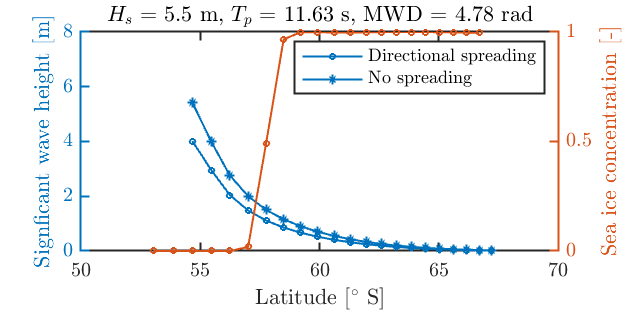


conFigure(11,2)
f = figure;
yyaxis left
plot(-lat(cell_lon_idx,lat_range),Hs,'o-')
hold on
plot(-lat(cell_lon_idx,lat_range),Hs_nospread,'*-')
xa = [0.3,0.3]; %[-lat(cell_lon_idx,lat_range(end)-1) -lat(cell_lon_idx,lat_range(end)-1)];
ya = [0.55,0.68]; %[Hs(3) Hs_nospread(3)];
%annotation('doublearrow',xa,ya,'Linewidth',1,'Head1Width',5,'Head2Width',5,'Head1Length',3,'Head2Length',3)
%text(-lat(cell_lon_idx,lat_range(end)+3)-0.25,(Hs(end-2) + Hs_nospread(end-2))/2+0.5,'Directional')
%text(-lat(cell_lon_idx,lat_range(end)+3)-0.25,(Hs(end-2) + Hs_nospread(end-2))/2-0.1,'spread')
%xlim([-80,-50])
ylim([0,8])
ylabel('Signficant wave height [m]')
%hold on
%plot(-lat(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1),swh_data(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1))
yyaxis right
plot(-lat(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1),aice_data(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1),'o-')
ylabel('Sea ice concentration [-]')
hold off
xlabel('Latitude [$^\circ$ S]')
title(sprintf('$H_s =$ %g m, $T_p =$ %g s, MWD = %g rad',round(Hs_init,2), round(Tp_init,2), round(mwd,2)),'Interpreter','latex')
legend('Directional spreading','No spreading','','Location','northeast')
exportgraphics(f,'1dprop.pdf','ContentType','vector')

% FLOE DEPENDENT SCATTERING AT THE ICE EDGE

% Calculate the wavelength using the deep water surface gravity wave dispersion relation wavelength
% lambda = gT^2/(2pi)
max_ppd = 20; % Maximum ppd for swell waves is about 20s in CAWCR
min_ppd = 0.1; % Minimum ppd for swell waves is about 20s in CAWCR
Tp = linspace(min_ppd,max_ppd,1000);
gravity = 9.80665;
lambda_p = (gravity*(Tp.^2))/(2*pi);

% Scattering calculation

% Parameters
max_energy_loss = 0.8;
min_energy_loss = 0;


clear beta_N legend_names
count = 1;
floe_sizes= round(NFSD,2);%[5,20,50,100]; %;[30,10,5]%5:5:30;
clear d_lambda
for n = 1:length(floe_sizes)
    floe_size = floe_sizes(n); % Diameter, m
    d_lambda(n,:) = floe_size./lambda_p;
    beta_N(n,:) = (max_energy_loss/2)*(tanh(d_lambda(n,:)-(5+0)/2)+1);
end



conFigure(10)
f = figure;
plot(d_lambda(1,:),beta_N(1,:))
hold on
legend_names(1) = sprintf("$d = $%g",floe_sizes(1));

%yline(max_energy_loss,'--')
%yline(min_energy_loss,'--')
xline(1,'--')
xline(5,'--')
grid on
xlabel('$d/\lambda$ [-]')
xlim([0,6])
ylim([-0.1,1.1])
%legend([legend_names,'',''])
ylabel('Proportion of wave energy lost [-]')

text(1-0.2,0.2,'$d \approx \lambda$')
text(5-0.4,0.2,'$d >> \lambda$')

exportgraphics(f,'beta_N.pdf','ContentType','vector')



conFigure(10)
f = figure;
for n = 1:length(floe_sizes)
    plot(lambda_p,beta_N(n,:))
    hold on
    legend_names(n) = sprintf("$d = $%g",floe_sizes(n));
end

grid on
xlabel('$\lambda$ [m]')
%xlim([min(lambda_,6])
ylim([-0.1,1.1])
legend([legend_names,'',''],'Location','eastoutside')

ylabel('Proportion of wave energy lost [-]')


exportgraphics(f,'lambda.pdf','ContentType','vector')


Tp = linspace(min_ppd,max_ppd,10);
gravity = 9.80665;
lambda_p = (gravity*(Tp.^2))/(2*pi);

clear beta_N legend_names
count = 1;
floe_sizes= round(NFSD,2);%[5,20,50,100]; %;[30,10,5]%5:5:30;
clear d_lambda
for n = 1:length(lambda_p)
    lambda = lambda_p(n); % Diameter, m
    d_lambda(n,:) = floe_size./lambda;
    beta_N(n,:) = (max_energy_loss/2)*(tanh(d_lambda(n,:)-(5+0)/2)+1);
end

conFigure(10)
f = figure;
for n = 1:length(lambda_p)
    plot(floe_sizes,beta_N(n,:))
    hold on
    legend_names(n) = sprintf("$d = $%g",lambda_p(n));
end

grid on
xlabel('$\lambda$ [m]')
%xlim([min(lambda_,6])
ylim([-0.1,1.1])
legend([legend_names,'',''],'Location','eastoutside')
ylabel('Proportion of wave energy lost [-]')


exportgraphics(f,'d.pdf','ContentType','vector')

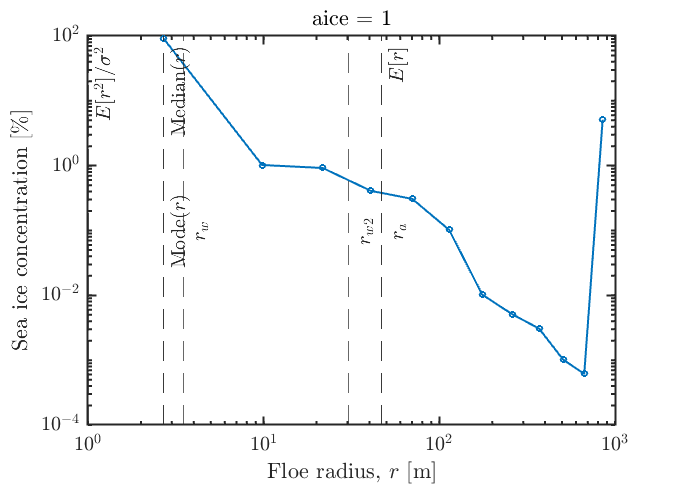

% Representative floe size for waves
aice = 1;
floe_size_data = [90 1 0.9 0.4 0.3 0.1 0.01 0.005 0.003 0.001 0.0006 5];
floe_size_data = floe_size_data./sum(floe_size_data);
floe_size_data = floe_size_data.*aice;

NCAT = ncread(filename,"NCAT");
NFSD = ncread(filename,"NFSD");
Nf = numel(NFSD);
Nc = numel(NCAT);

[floe_binwidth, floe_rad_l, floe_rad_h] = cice_parameters(NFSD);

E_r = floe_size_data*NFSD; % Mean = Expectation of F(r)
E_r2 = (1/aice)*floe_size_data*((NFSD-E_r).^2); % Variance = Second moment of F(r)
sigma2_r = (1/aice)*floe_size_data*((NFSD-E_r).^2);
median_r = NFSD(find(abs(cumsum(floe_size_data)-0.5) == min(abs(cumsum(floe_size_data)-0.5))));
mode_r = NFSD(find(floe_size_data == max(floe_size_data)));


r_a = (1/aice)*(floe_size_data*NFSD);

% r_w, representative radius for incoming waves
% See if floes in the largest floe size category are dominant, else,
% calculate the mean from the distribution ignoring that class
%r_w = (1/aice)*(floe_size_data*(NFSD.^2));

if max(floe_size_data) == floe_size_data(end)
    r_w = (1/aice)*(floe_size_data*NFSD);
else
    floe_size_data_adjusted = floe_size_data(1:end-1)./sum(floe_size_data(1:end-1)); % normalise
    r_w = (1/aice)*(floe_size_data_adjusted*NFSD(1:end-1));

    floe_size_data_adjusted = floe_size_data(2:end-1)./sum(floe_size_data(2:end-1)); % normalise
    r_w2 = (1/aice)*(floe_size_data_adjusted*NFSD(2:end-1));
end



conFigure(12)
f = figure;
loglog(NFSD', floe_size_data*100,'-o')
xlabel('Floe radius, $r$ [m]')
ylabel('Sea ice concentration [\%]')

xline(E_r,'--',{'$E[r]$'},'Interpreter','latex')
xline(median_r,'--',{'Median$(r)$'},'Interpreter','latex')
xline(mode_r,'--',{'Mode$(r)$'},'Interpreter','latex','LabelVerticalAlignment','middle')
xline(r_a,'--',{'$r_a$'},'Interpreter','latex','LabelVerticalAlignment','middle')
xline(r_w,'--',{'$r_w$'},'Interpreter','latex','LabelVerticalAlignment','middle')
xline(r_w2,'--',{'$r_{w2}$'},'Interpreter','latex','LabelVerticalAlignment','middle')
%xline(sigma_r,'--',{'$\sigma_r$'},'Interpreter','latex')
%xline(E_r2,'--',{'$E[r^2]$'},'Interpreter','latex')
xline(E_r2/(sigma_r),'--',{'$E[r^2]/\sigma^2$'},'Interpreter','latex')


title(sprintf('aice = %g',aice))

exportgraphics(f,'loglogfsd.pdf','ContentType','vector')

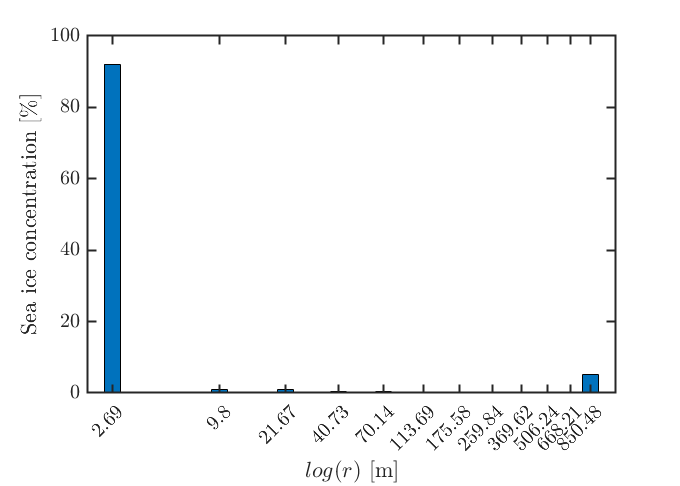


f = figure;
bar(log(NFSD), floe_size_data*100)
xlabel('$log(r)$ [m]')
xticks(log(NFSD))
xticklabels(num2str(round(NFSD,2)))
ylabel('Sea ice concentration [\%]')
exportgraphics(f,'barfsd.pdf','ContentType','vector')

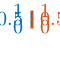



conFigure(11,2)
f= figure;
yyaxis left

plot(-transect.tlat(wave_lat:-1:wave_lat-length_transect+1),Hs)

Unable to resolve the name 'transect.tlat'.

xlim([50,70])

yyaxis right
plot(-transect.tlat,aice_test)
hold off
legend('SWH','Ice concentration','Location','northeast')



figure
yyaxis left
plot(-lat_vec, swh_data_vec)
ylabel('Significant wave height [m]')
yyaxis right 
plot(-lat_vec, aice_data_vec)
ylabel('Areal ice concentration [-]')
xlabel('Latitude [$^\circ$ S]')

fsdrad_data = data_format_sector(filename,"fsdrad",sector);
fsdrad_data_vec= fsdrad_data(lon_pos,lat_range);

figure
yyaxis left
plot(-lat_vec, swh_data_vec)
ylabel('Significant wave height [m]')
yyaxis right 
plot(-lat_vec, fsdrad_data_vec)
ylabel('Mean floe size [m]')
xlabel('Latitude [$^\circ$ S]')

% Plot the map of the propagated waves through ice 


% JUNK CODE


land_mask = isnan(aice_data(cell_lon_idx,:));
aice_test = zeros(size(aice_data(cell_lon_idx,:)));
aice_test(land_mask) = NaN;

for i = 2:length_transect
    conc = aice_test(wave_lat-i+1); %aice_data(cell_lon_idx,wave_lat-i+1);

n_vec =     1.0000    2.5000    5.0000   10.0000


    hice = hice_data(cell_lon_idx,wave_lat-i+1);
    if isnan(conc) % Land
        S_attn(i,:) = zeros(1,nw);
    else
        if conc > tolice && hice > thice
            for j = 1:16
                attn_spec(i,j) = fn_Attn_MBK(omega(j));
                alpha(i,j) = conc*attn_spec(i,j)/0.7;
                exp_term(i,j) = exp(-alpha(i,j)*L(i));
                S_attn(i,j) = S_attn(i-1,j).*exp_term(i,j);
            end
        else
            S_attn(i,:) = S_attn(i-1,:);
        end

int_D = 2.5726

int_D = 2.0287

int_D = 1.5362

int_D = 1.1069

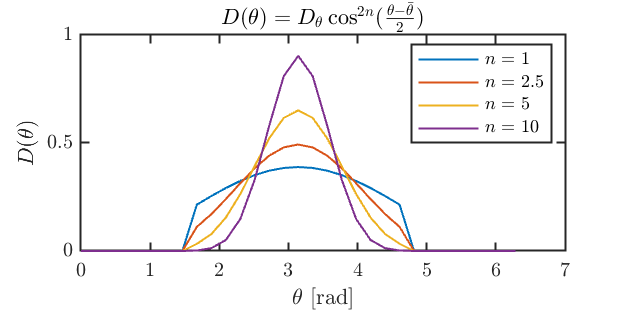

    end
end

sub_Uncoupled


fn_Attn_MBK(omega(1))


for i = 1:length_transect
    Hs(i) = 4*sqrt(sum(S_attn(i,:).*dwavefreq)); % sig wave height
end


addpath /Users/noahday/GitHub/CICE-plotting-tools/functions
thn = 31;
mwd = pi;
theta_vec = linspace(mwd-pi,mwd+pi,thn);
theta0 = pi;
n_vec = [1,2.5,5,10]
clear D int_D
count = 1;
for n = n_vec
    D(count,:) = cos((theta_vec-theta0)/2).^(2*n);
    % Integration step
    low_bnd = theta0 - pi/2 < theta_vec;
    upp_bnd = theta_vec < theta0 + pi/2;
    bnd = low_bnd.*upp_bnd;
    D(count,~bnd) = 0;
    dtheta = theta_vec(1:end) - [0,theta_vec(1:end-1)];
    int_D = sum(D(count,:).*dtheta)
    D(count,:) = D(count,:)./int_D;
    count = count + 1;
end
conFigure(11,2)
f = figure;
plot(theta_vec,D)
legend(sprintf('$n =$ %g',n_vec(1)), sprintf('$n =$ %g',n_vec(2)), sprintf('$n =$ %g',n_vec(3)), sprintf('$n =$ %g',n_vec(4)))
ylabel('$D(\theta)$')
xlabel('$\theta$ [rad]')
title('$D(\theta) = D_{\theta}\cos^{2n}(\frac{\theta-\bar{\theta}}{2})$')
exportgraphics(f,'dirspread_n.pdf','ContentType','vector')

## FUNCTIONS

function [S,omega,T] = SDF_Bretschneider(Hs,Tm,nw)
    fmin = 1/1000;%1/50;%1/16; % freq min
    fmax = 1;%1/2;%1/6; % freq max
    om1=2*pi*fmin; % ang freqs, rad/s
    om2=2*pi*fmax;
    om_0 = (om2 - om1)/(nw-1); % steps
    gravit = 9.81;
    % Calculate wave numbers and wavelengths
    for lp_i=1:nw
      omega(lp_i)        = om1 + (lp_i-1)*om_0; % Frequency, rad/s
      T(lp_i)            = 2*pi/omega(lp_i); % Period, s
      lam_wtr_in(lp_i)   = gravit*(T(lp_i)^2)/2/pi; % Wave number
      k_wtr_in(lp_i)     = 2*pi/lam_wtr_in(lp_i); % Wave length
    end
    
    tmin = 1/fmax;
    tmax = 1/fmin;
    t1 = tmin;
    t2 = tmax;
    t_0 = (t2-t1)/(nw-1);
    
    
    %clear omega
    % Define steps in terms of period not frequency
    %for lp_i=1:nw
    %   T(lp_i) = t1 + (lp_i-1)*t_0;
    %   omega(lp_i) = 2*pi/T(lp_i);
    %end


    %  omega(lp_i)        = om1 + (lp_i-1)*om_0; % Frequency, rad/s
    %  T(lp_i)            = 2*pi/omega(lp_i); % Period, s
    %  lam_wtr_in(lp_i)   = gravit*(T(lp_i)^2)/2/pi; % Wave number
    %  k_wtr_in(lp_i)     = 2*pi/lam_wtr_in(lp_i); % Wave length
    %end
    



    
    for lp_i = 1:nw
        om_m = 2*pi/Tm; % 1/s
        tau(lp_i)  = 2*pi/omega(lp_i); % s
    end
    
    moment_no = 0;
    f1 = (5/16)*(Hs.^2)*(om_m.^4); % m^2/s^4
    f2 = omega.^(moment_no-5); % rad/s^-5
    f3 = exp(-1.25*((tau/Tm).^4)); % dimensionless (as exponentials have no dimension)

    S = f1.*f2.*f3; % rad x m^2 s/rad
end

function attn_spec = fn_Attn_MBK(local_wave_spec)
    % Attenuate according to Meylan et al. (2014)
    dum_om = local_wave_spec;
    attn_fac = 1;
    beta0 = 5.376168295200780e-005;
    beta1 = 2.947870279251530e-005;
    
    fn_Attn_MBK1 = beta0*(dum_om.^2) + beta1*(dum_om.^4);
    
    attn_spec = attn_fac*fn_Attn_MBK1;
end


function attn_spec = fn_Attn_MBKT(local_wave_period)
    % Attenuate according to Meylan et al. (2014)
    dum_T = local_wave_period;
    attn_fac = 1;
    a = 2.12e-3; % s^2/m
    b = 4.59e-2; % s^4/m
    
    fn_Attn_MBK2 = a*(dum_T.^(-2)) + b*(dum_T^(-4));
    
    attn_spec = attn_fac*fn_Attn_MBK2;
end

function [int_D,D,theta_vec] = cosine_spreader(mwd,thn,n)
    % Spread the wave spectrum through angular space
    % theta is the mean wave direction [rad], South = 0
    % and integrate over -pi/2 to pi/2
    % theta0 is the MWD
    % D is the energy in directional spectrum
    % theta_vec is the corresponding angles for D
    % n is the index

    theta_vec = linspace(mwd-pi,mwd+pi,thn);
    theta0 = mwd;
    low_bnd = theta0 - pi/2 < theta_vec;
    upp_bnd = theta_vec < theta0 + pi/2;
    bnd = low_bnd.*upp_bnd;
    D = zeros(1,thn);
    %D = (2/pi).*(cos(theta_vec-theta0)).^n;
    %D(~bnd) = 0;
    % Integration step
    %upper = pi/2;
    %lower = 3*pi/2;
    %low_bnd = lower < theta_vec;
    %upp_bnd = theta_vec < upper; 
    %%bnd = low_bnd | upp_bnd;
    %D(~bnd) = 0;
    %dtheta = theta_vec(1:end) - [0,theta_vec(1:end-1)];
    %int_D = sum(D.*dtheta);
    D(:) = cos((theta_vec-theta0)/2).^(2*n);
    % Integration step
    low_bnd = theta0 - pi/2 < theta_vec;
    upp_bnd = theta_vec < theta0 + pi/2;
    bnd = low_bnd.*upp_bnd;
    D(~bnd) = 0;
    dtheta = theta_vec(1:end) - [0,theta_vec(1:end-1)];
    int_D = sum(D.*dtheta);
    D = D./int_D;

end

function [data_out] = data_format_cawcr(filedir,variable)
    % OM2 grid

    lon = ncread(filedir,'LON');
    lat = ncread(filedir,'LAT');

    row = 281;
    dim = 3;
    data1 = ncread(filedir, variable);
    
    latitude = [-90,90];
    longitude = [-180,180];
    

    data1 = rearrange_matrix(data1,row,dim);
    
    % fixing data
    [m, ~] = size(lon);
    lon = [lon; lon(end,:) + 360/m];
    lat = [lat; lat(end,:)];
    data_out = [data1; data1(end,:,:)];

end
